clear
close
clc


RGB = imread("Winter.png");
R = RGB(:,:,1); 
G = RGB(:,:,2); 
B = RGB(:,:,3);

figure
imshow(RGB);
title('Image in RGB Color Space');
figure

imshow(R);
imshow(G);
imshow(B);




YCBCR = rgb2ycbcr(RGB);


Y = YCBCR(:,:,1); 
Cb = YCBCR(:,:,2); 
Cr = YCBCR(:,:,3);

figure ; clf;
imshow(YCBCR);
title('Image in YCbCr Color Space');

imshow(Y);
title('Image in Y Color Space');
imshow(Cb);
title('Image in Cb Color Space');
imshow(Cr);
title('Image in Cr Color Space');

% Question 3- Reducing Sampling

[nCb,nCr]= downsample(Cb,Cr);
newnCbCr= cat(3, Y, nCb,nCr);
RGB2 = ycbcr2rgb(newnCbCr)
imshowpair(RGB,RGB2,"montage");
imshow(RGB2)
imshow(newnCbCr)



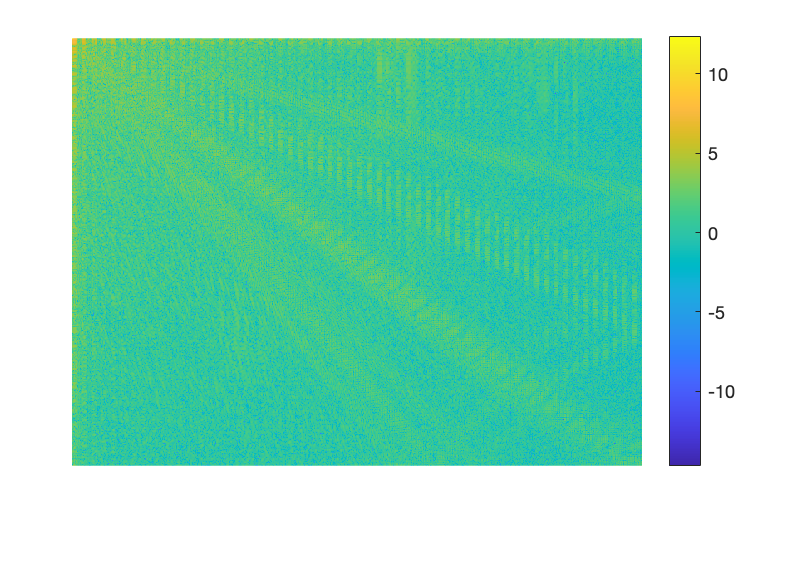

% Question 4- 2D DCT transform

RGB = imread('Cluster word.png');
I = im2gray(RGB);
J = dct2(I);
imshow(log(abs(J)),[])
colormap parula
colorbar

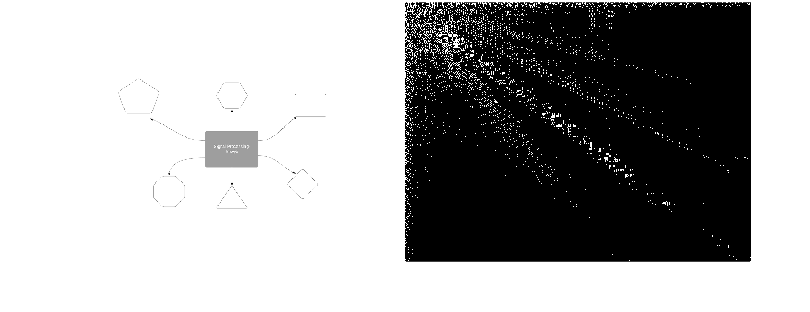

J(abs(J) < 10) = 0;
%K = idct2(J);
%K = rescale(K);
montage({I,J})
title('Original Grayscale Image (Left) and Processed Image (Right)');